# Base estimators

Tutorial file for showcasing plain BVARs, and their most important actions

- Estimation

- Unconditional forecast with reduced form models

- Types of structural identification

- Impulse responses

- Historical structural shock decomosition

- Structural shock decomposition of unconditional forecast

- FEVD

- Conditional forecast

## Housekeeping

clear
close all
clear classes

rehash path

  
import base.*


## Convenience functions

The `extremesFunc` function compresses any number of samples (draws from the posterior) into two numbers - the minimum and the maximum.

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

medianFunc = @(x) median(x, 2);

flatFunc = @(x) x(:, :);

defaultColors = get(0, "defaultAxesColorOrder");


## Number of Samples

numPresampled = 100;

## Prepare meta information for the models

Note that the meta information are common to all plain BVAR models, regardless of the specific estimator used.

The properties specific to all BVARs are the followings:

**endogenousNames **– list of endogenous variables

**exogenousNames **– list of exogenous variables

**order **– order, number of lags   

**intercept** – logical variable; set to **"**`true`**"** to include an intercept, or **"**`false`**"** for models without a constant term.

**estimationSpan** – the time range over which the model is estimated.

**identificationHorizon** – the maximum length of the identification period, corresponding to the length of the structural impulse responses.

**shockNames** – user-defined names of structural shocks. If not specified, the endogenous variables’ names are used with the suffix `_shock`.



estimStart = datex.q(1975,1);
estimEnd = datex.q(2014,4);
estimSpan = datex.span(estimStart, estimEnd);

meta = Meta( ...
    endogenousNames=["DOM_GDP", "DOM_CPI", "STN"], ...
    exogenousNames="Oil", ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    identificationHorizon=12, ...
    shockNames=["DEM", "SUP", "POL"] ...
);


## Specifying and loading input data


inputTbl = tablex.fromFile("exampleData.csv");
dataH = DataHolder(meta, inputTbl);

## Reduced form models

There are several common hyperparameters for plain BVARs, mainly the hyperparameters. The default values are given in the brackets.

**Autoregression (0.8)** –  prior mean on the first own lag

**Lambda1 (0.1)** – Controls the overall degree of shrinkage toward the prior mean.

**Lambda2 (0.5)** – Adjusts the relative tightness across equations, scaling by variable variance.

**Lambda3 (1)** –  Lag decay, governs how rapidly the prior tightness decreases with increasing lag order.

**Lambda4 (100)** –  Determines the tightness applied to coefficients of exogenous regressors.

**Lambda5 (1/100)** –  Controls the shrinkage on block exogenous components.

**Exogenous (false)** –  Contoling whether to use prior on exgenous variables

### Basic BVARs

However, there are also some estimator-specific settings. All settings—both common and specific—can be overridden by providing new values for these options when configuring the estimator, as demonstrated in the `Minnesota` example below

#### **Ordinary**

**Important note **– mainly usage is to combine this with dummy observation e.g Minnesota 

% estimatorR1 = estimator.Ordinary(meta)

#### **Minnesota priors**

Estimator sepcific settings:

**Sigma (ar)** – controls the priors used for calculating the covariance matrix. Possible values are:

- **ar** – uses the variances matrix from estimated AR models foer each variable (with the same order as the final model),

- **diag** – uses only the diagonal elements of the covariance matrix from an estimated VAR (with the same order as the final model),

- **full** – uses the full covariance matrix from an estimated VAR (with the same order as the final model)

estimatorR1 = estimator.Minnesota(meta, Sigma = "diag", Autoregression = 1)

estimatorR1 =   Minnesota with properties:

                Settings: [1×1 base.estimator.settings.Minnesota]
             Description: "VAR with Minnesota prior"
                Category: "Plain estimators"
           HasCrossUnits: 0
         CanBeIdentified: 1
          CanHaveDummies: 1
                 Sampler: []
           SampleCounter: 0
           HistoryDrawer: []
     UnconditionalDrawer: []
       ConditionalDrawer: []
    IdentificationDrawer: []
          ShortClassName: 'Minnesota'
         BeenInitialized: 0


#### **Normal Wishart priors**

Estimator sepcific settings:

**Sigma (ar)** – controls the priors used for calculating the covariance matrix. Possible values are:

- **ar** – uses the variances matrix from estimated AR models for each variable (with the same order as the final model),

- **eye** – using the identity matrx

% estimatorR1 = estimator.NormalWishart(meta)

#### **Normal Diffuse prior**

There are no estimator-specific settings other than the hyperparameters.

% estimatorR1 = estimator.NormalDiffuse(meta)

#### **Individual Normal Wishart prior**

Estimator sepcific settings:

**Sigma (ar)** – controls the priors used for calculating the covariance matrix. Possible values are:

- **ar** – uses the variances matrix from estimated AR models foer each variable (with the same order as the final model),

- **eye** – using the identity matrx

% estimatorR1 = estimator.IndNormalWishart(meta)

#### **Flat priors**

There are no estimator-specific settings other than the hyperparameters.

% estimatorR1 = estimator.Flat(meta)

### Stochastic volatility (SV) BVARs - SV models from BEAR5

Note that SV models for large shocks will be discussed in a separate tutorial

All SV models in this group (including the general time varying model) share the same estimator specific setings

**HeteroskedasticityAutoRegression **– prior on the autoregression in heteroskedasticity (gamma in BEAR5)

**HeteroskedasticityShape **– prior on the shape of the inverse gamma distribution of the variance of the residual in heteroskedasticity (alpha in BEAR5)

**HeteroskedasticityScale **– prior on the scale of the inverse gamma distribution of the variance of the residual in heteroskedasticity (delta in BEAR5)

#### Standard SV model ( Cogley and Sargent (2005) )

% estimatorR1 = estimator.CogleySargentSV(meta)

#### SV model with Random Inertia 

**HeteroskedasticityAutoRegressionVariance **– prior on the variance of the autoregression in heteroskedasticity (zeta0 in BEAR5)

% estimatorR1 = estimator.RandomInertiaSV(meta)

#### SV model for large Bayesian VAR ( Carriero et al. (2012) )

% estimatorR1 = estimator.CarrieroSV(meta)

### Time-varying (TV) BVARs

#### **Time varying dynamic parameters only**

There are no estimator-specific settings other than the hyperparameters.

% estimatorR1 = estimator.BetaTV(meta)

#### **Time varying dynamic parameters and stochastic volatility**

As mentioned above the common SV setings could be applied here as well

% estimatorR1 = estimator.GeneralTV(meta)

## Creating dummy observations

The majority of the reduced form estimators could be combined by dummy observations, the feature could be tested by 

estimatorR1.CanHaveDummies

ans = logical
   1


Each dummy observation has its own overla tightness hyperparameter **Lambda,** however its default value differs across dummies.

### Sum of coefficients dummy

Dummy specific hyperparameters

**Lambda (0.1)  **

sumCoeffD = dummies.SumCoeff(Lambda=1e-4);
sumCoeffD.Lambda

ans = 1.0000e-04

### **Initial observation dummy**

Dummy specific hyperparameters

**Lambda (0.001)  ** 

initObsD = dummies.InitialObs();

### **Minnesota dummy**

Dummy specific hyperparameters

**Lambda (0.1) **

**LagDecay (1)**  –  Lag decay, governs how rapidly the prior tightness decreases with increasing lag order. 

**Autoregression (0.8**)   –   Prior mean on the first own lag

**ExogenousLambda (100) **  –   Determines the tightness applied to coefficients of exogenous regressors.

**Exogenous (false)** –  Contoling whether to use prior on exgenous variables

minnesotaD = dummies.Minnesota();

## Long-run dummies

Dummy specific hyperparameters

**Lambda (1)**

Note that for this dummz the long run relationships should be added as an input table or matrix.

longRunTbx = tablex.forLongRunDummies(meta);
longRunTbx{"DOM_GDP", "DOM_GDP"} = 1;
longRunTbx{"DOM_CPI", "DOM_CPI"} = 1;
longRunTbx{"DOM_CPI", "STN"} = 1;
longRunTbx{"STN", "DOM_CPI"} = -1;
longRunTbx{"STN", "STN"} = 1;

longRunD = dummies.LongRun(Table=longRunTbx,Lambda=1e-4);
longRunD.Lambda

ans = 1.0000e-04

longRunD.Table

ans = 3×3 table
               DOM_GDP    DOM_CPI    STN
               _______    _______    ___

    DOM_GDP       1          0        0 
    DOM_CPI       0          1        1 
    STN           0         -1        1 


## Creating the reduced form model


modelR1 = ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR1 ...
);


### Adding dummy observations

Users can also add the dummy observations created above to the reduced-form estimator as shown below. Combining multiple dummies is also allowed.

% modelR1 = ReducedForm( ...
%     meta=meta ...
%     , dataHolder=dataH ...
%     , estimator=estimatorR1 ...
%     , dummies={initObsD, minnesotaD}
% );

## Estimation/sampling of the reduced form model 


modelR1.initialize();
info0 = modelR1.presample(numPresampled);


 Presampling from posterior (Minnesota) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelR1.Presampled{1}.beta

ans =     0.9050
   -0.0740
    0.0548
   -0.0984
    0.0200
   -0.0336
   -0.0810
    0.0179
   -0.0190
    0.0104


## Running Unconditional forecast 

### Settig up the forecast range and run the forecast

fcastStart = datex.shift(modelR1.Meta.EstimationEnd, -10); %The forecast starts 10 periods prior to the end of the estimation span.
fcastEnd = datex.shift(modelR1.Meta.EstimationEnd, 0); %The forecast ends at the end of the estimation window.
fcastSpan = datex.span(fcastStart, fcastEnd);

fcastStart, fcastEnd

fcastStart = datetime
   2012-Q2


fcastEnd = datetime
   2014-Q4



fcastTbx = modelR1.forecast(fcastSpan);
fcastPrctileTbx = tablex.apply(fcastTbx, prctileFunc);
fcastPrctileTbx = tablex.flatten(fcastPrctileTbx); %keeping only the pctiles set at the beginning of the file (10, 50, 90)



### Visualize the unconditional forecast

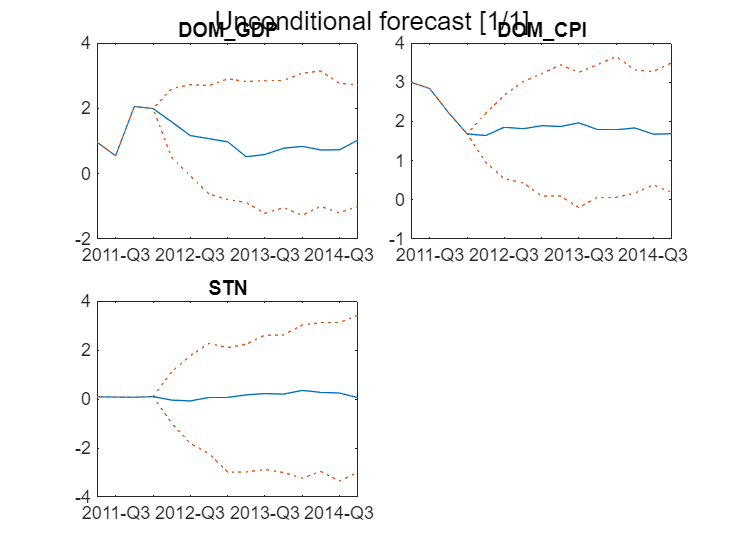

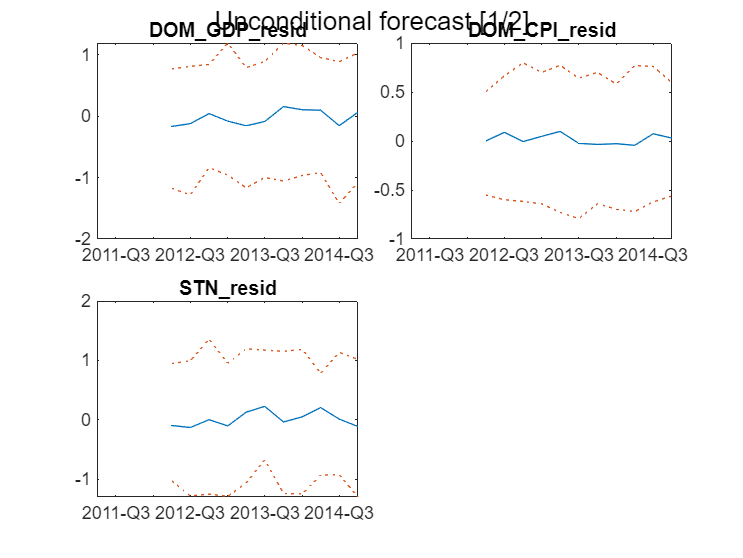

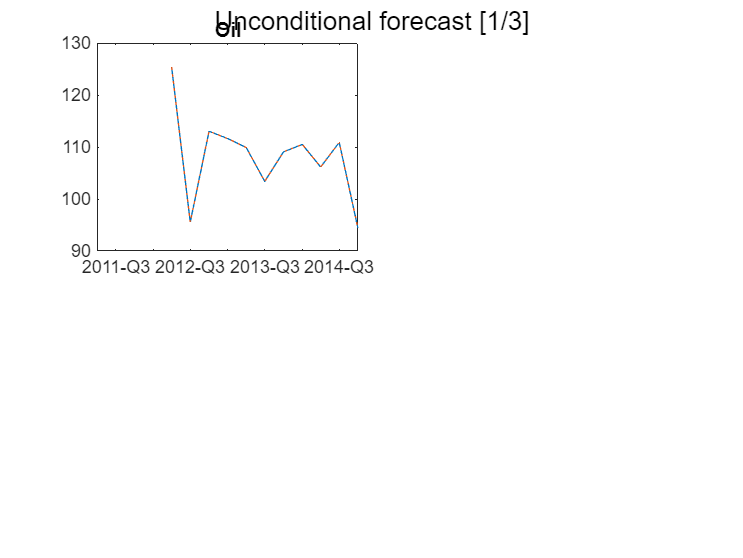

ans = 1×3 cell array
    {1×1 Figure}    {1×1 Figure}    {1×1 Figure}


chartpack.forecastPercentiles( ...
    fcastPrctileTbx, modelR1, FigureTitle ="Unconditional forecast")

## Identification

### Cholesky

You can use the Cholesky decomposition also with a different ordering of endogenous variables than in the meta specification. However, if the trailing part of the order matches the meta order, you may omit that portion.

#### Setting up the identifier


identChol = identifier.Cholesky(ordering=["DOM_CPI", "DOM_GDP", "STN"]); %reordering the variables

modelS1 = Structural(reducedForm=modelR1, identifier=identChol);
modelS1.initialize();

info0 = modelS1.presample(numPresampled);


 Presampling from posterior (Minnesota) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS1.Presampled{1}

ans = struct with fields:
                  beta: [42×1 double]
                 sigma: [3×3 double]
    IdentificationDraw: [1×1 struct]
                     D: [3×3 double]


#### Checking transition matrices

modelS1.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {12×1 cell}
        C: {12×1 cell}
    Sigma: [3×3 double]


modelS1.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.8462    0.0610    0.0605
   -0.0428    1.0215    0.0427
   -0.0247    0.0355    0.9218
   -0.0271   -0.0227   -0.0143
   -0.0048   -0.1172    0.0272
   -0.0135   -0.0099   -0.0241
   -0.1009   -0.0000    0.0162
   -0.0176   -0.0240    0.0197
    0.0055   -0.0088   -0.0149
   -0.0094    0.0051    0.0044


modelS1.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.8462    0.0610    0.0605
   -0.0428    1.0215    0.0427
   -0.0247    0.0355    0.9218
   -0.0271   -0.0227   -0.0143
   -0.0048   -0.1172    0.0272
   -0.0135   -0.0099   -0.0241
   -0.1009   -0.0000    0.0162
   -0.0176   -0.0240    0.0197
    0.0055   -0.0088   -0.0149
   -0.0094    0.0051    0.0044


#### Checking scaling matrix

modelS1.Presampled{1}.D

ans =          0    0.5331         0
    0.8042         0         0
         0         0    0.8590


modelS1.Presampled{2}.D

ans =          0    0.5331         0
    0.8042         0         0
         0         0    0.8590


### Instant zeros restrictions

#### Specify instant zero restrictions 

- Create an empty table for instant zero restrictions using `tablex.forInstantZeros`

- The table has endogenous variables in rows, shocks in columns

- Fill in zeros for the elements to be restricted

- The algorithm can only handle *underdetermined* systems, meaning it musthave at least one "degree of freedom"; this means the max number of zero restrictions is  `n * (n-1) / 2 - 1`

- The algorithm is able handle an edge case of no restrictions - it simply produces fully randomized unconstrained factors of the covariance matrix


instantZerosTbl = tablex.forInstantZeros(modelR1);
instantZerosTbl{"DOM_CPI", "DEM"} = 0;
instantZerosTbl{"STN", "SUP"} = 0;
instantZerosTbl

instantZerosTbl = 3×3 table
               DEM    SUP    POL
               ___    ___    ___

    DOM_GDP    NaN    NaN    NaN
    DOM_CPI      0    NaN    NaN
    STN        NaN      0    NaN



tablex.writetable(instantZerosTbl, "instantZerosTbl.xlsx");
instantZerosTbl = tablex.readtable("instantZerosTbl.xlsx", convertTo=@double);

#### Seting up the identifier

identInstantZeros = identifier.InstantZeros(table=instantZerosTbl);

modelS2 = Structural(reducedForm=modelR1, identifier=identInstantZeros);
modelS2.initialize();
info1 = modelS2.presample(numPresampled);


 Presampling from posterior (Minnesota) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS2.Presampled{1}

ans = struct with fields:
                  beta: [42×1 double]
                 sigma: [3×3 double]
    IdentificationDraw: [1×1 struct]
                     D: [3×3 double]


#### Checking transition matrices

modelS2.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {12×1 cell}
        C: {12×1 cell}
    Sigma: [3×3 double]


modelS2.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.9790    0.0258    0.0294
   -0.0537    1.0285    0.0222
    0.0211    0.0698    0.9743
   -0.0878    0.0138   -0.0081
   -0.0115   -0.1000    0.0197
   -0.0465   -0.0272   -0.0949
   -0.0992    0.0178   -0.0016
   -0.0003   -0.0578   -0.0263
   -0.0005   -0.0125    0.0010
    0.0136   -0.0051    0.0151


modelS2.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.9790    0.0258    0.0294
   -0.0537    1.0285    0.0222
    0.0211    0.0698    0.9743
   -0.0878    0.0138   -0.0081
   -0.0115   -0.1000    0.0197
   -0.0465   -0.0272   -0.0949
   -0.0992    0.0178   -0.0016
   -0.0003   -0.0578   -0.0263
   -0.0005   -0.0125    0.0010
    0.0136   -0.0051    0.0151


#### Checking scaling matrix

modelS2.Presampled{1}.D

ans =    -0.6713         0    0.4730
         0    0.5331         0
    0.4428         0    0.7170


modelS2.Presampled{2}.D

ans =     0.6053         0    0.5655
         0   -0.5331         0
    0.5294         0   -0.6466


### General restrictions

#### Specify restrictions

General restrictions are strings representing an expression that evaluates to `true` or `false`, using the following references to "system properties"

- `$SHKRESP` — shock responses

- `$FEVD` — forecast variance contributions

- `$SHKCONT` — histrorical shock contributions

- `$SHKEST` — histroical estimated shocks 

Each restriction should be included as a string element in a vector defining the desired restrictions for the structural VAR

#### **Restriction on simualtion properties**

For shock responses (`$SHKRESP`) and forecast error variance (`$FEVD`), ach element in the vector represents one restriction and should specify:

- the **period**,

- the **endogenous variable**,

- the **shock name**, and

- the **expected sign or magnitude** of the response/contribution.

The general syntax follows the pattern:

`"$SHKRESP(period, 'endogenousName', 'shockName') >/< X"`

`"$FEVD(period, 'endogenousName', 'shockName') >/< X"`

signStrings = [
    "$SHKRESP(2, 'DOM_GDP', 'DEM') > 0"
    "$SHKRESP(2, 'DOM_CPI', 'DEM') > 0"

    "$SHKRESP(3, 'DOM_GDP', 'DEM') > 0"
    "$SHKRESP(3, 'DOM_CPI', 'DEM') > 0"

    "$SHKRESP(2, 'DOM_GDP', 'SUP') < 0"
    "$SHKRESP(2, 'DOM_CPI', 'SUP') > 0"

    "$SHKRESP(3, 'DOM_GDP', 'SUP') < 0"
    "$SHKRESP(3, 'DOM_CPI', 'SUP') > 0"
]

signStrings = 8×1 string array
    "$SHKRESP(2, 'DOM_GDP', 'DEM') > 0"
    "$SHKRESP(2, 'DOM_CPI', 'DEM') > 0"
    "$SHKRESP(3, 'DOM_GDP', 'DEM') > 0"
    "$SHKRESP(3, 'DOM_CPI', 'DEM') > 0"
    "$SHKRESP(2, 'DOM_GDP', 'SUP') < 0"
    "$SHKRESP(2, 'DOM_CPI', 'SUP') > 0"
    "$SHKRESP(3, 'DOM_GDP', 'SUP') < 0"
    "$SHKRESP(3, 'DOM_CPI', 'SUP') > 0"



fevdStrings = [
    "$FEVD(2, 'DOM_GDP', 'DEM') > 0"
]

fevdStrings = "$FEVD(2, 'DOM_GDP', 'DEM') > 0"

**Restriction on historical properties**

The syntax is very similar for historical shock contributions (`$SHKCONT`); however, for this option, the user must specify a **historical date **(instead of the simulation period) within the estimation range at which the restriction should be applied.

`"$SHKCONT('dateString', 'endogenousName', 'shockName') >/< X"`

contStrings = [
    "$SHKCONT(2014-Q1, 'DOM_GDP', 'DEM') > 0"
]

contStrings = "$SHKCONT(2014-Q1, 'DOM_GDP', 'DEM') > 0"

For the histrorical estimated shocks($`SHKEST`), only the magnitude of the shock matters. Therefore, in this case, the user does not need to specify the name of the endogenous variable.

`"$SHKEST('dateString', 'shockName') >/< X" `

estStrings = [
    "$SHKEST(2014-Q1, 'DEM') > 0"
]

estStrings = "$SHKEST(2014-Q1, 'DEM') > 0"

#### Seting up the identifier (use only sign restrictions)

identVerifiables = identifier.Verifiables( ...
    signStrings, ...
    maxCandidates=50 ...
);

modelS3 = Structural(reducedForm=modelR1, identifier=identVerifiables);
modelS3.initialize();
info1 = modelS3.presample(numPresampled);


 Presampling from posterior (Minnesota) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS3.Presampled{1}

ans = struct with fields:
                  beta: [42×1 double]
                 sigma: [3×3 double]
    IdentificationDraw: [1×1 struct]
                     D: [3×3 double]


#### Checking transition matrices

modelS3.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {12×1 cell}
        C: {12×1 cell}
    Sigma: [3×3 double]


modelS3.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.9147    0.0125    0.0986
    0.0209    1.0584    0.0282
   -0.0175    0.0144    0.9654
   -0.0958    0.0126    0.0039
   -0.0128   -0.1367    0.0156
   -0.0507   -0.0012   -0.0245
   -0.0544    0.0122    0.0234
   -0.0031   -0.0540    0.0553
   -0.0010   -0.0209   -0.0342
   -0.0039    0.0142    0.0230


modelS3.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.9147    0.0125    0.0986
    0.0209    1.0584    0.0282
   -0.0175    0.0144    0.9654
   -0.0958    0.0126    0.0039
   -0.0128   -0.1367    0.0156
   -0.0507   -0.0012   -0.0245
   -0.0544    0.0122    0.0234
   -0.0031   -0.0540    0.0553
   -0.0010   -0.0209   -0.0342
   -0.0039    0.0142    0.0230


#### Checking scaling matrix

modelS3.Presampled{1}.D

ans =     0.0677    0.0293   -0.8546
   -0.1094    0.5277    0.0371
   -0.7938   -0.0702   -0.0780


modelS3.Presampled{2}.D

ans =     0.6999   -0.0474    0.4162
   -0.1316    0.4668    0.3904
    0.3736    0.2531   -0.6421


## Impulse respones (IRF)

### Cholesky

respTbl1 = modelS1.simulateResponses();
respTbl1 = tablex.apply(respTbl1, prctileFunc);
respTbl1 = tablex.flatten(respTbl1);


  (Minnesota) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




respTbl1

chartpack.responsePercentiles( ...

respTbl1 = 16×9 timetable
     Time                 DOM_GDP___DEM                           DOM_GDP___SUP                            DOM_GDP___POL                        DOM_CPI___DEM                       DOM_CPI___SUP                          DOM_CPI___POL                             STN___DEM                              STN___SUP                          STN___POL          
    _______    ___________________________________    _____________________________________    _____________________________________    _____________________________    ___________________________________    ___________________________________    ______________________________________    ________________

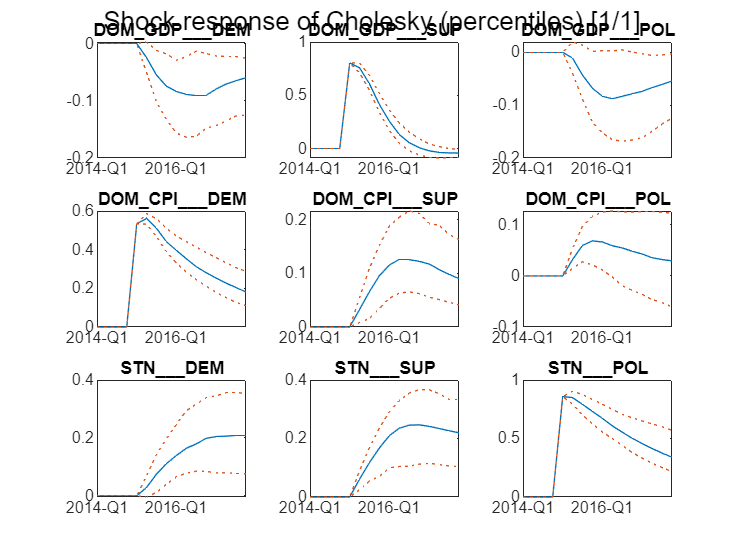

    respTbl1, modelS1 ...
    , "figureTitle", "Shock response of Cholesky (percentiles)" ...
);

### Instant zeros


respTbl2 = modelS2.simulateResponses();


  (Minnesota) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



respTbl2 = tablex.apply(respTbl2, prctileFunc);
respTbl2 = tablex.flatten(respTbl2);

respTbl2

respTbl2 = 16×9 timetable
     Time                  DOM_GDP___DEM                            DOM_GDP___SUP                            DOM_GDP___POL                           DOM_CPI___DEM                        DOM_CPI___SUP                         DOM_CPI___POL                          STN___DEM                             STN___SUP                            STN___POL            
    _______    _____________________________________    _____________________________________    _____________________________________    ___________________________________    ________________________________    ___________________________________    ________________________________    ____________

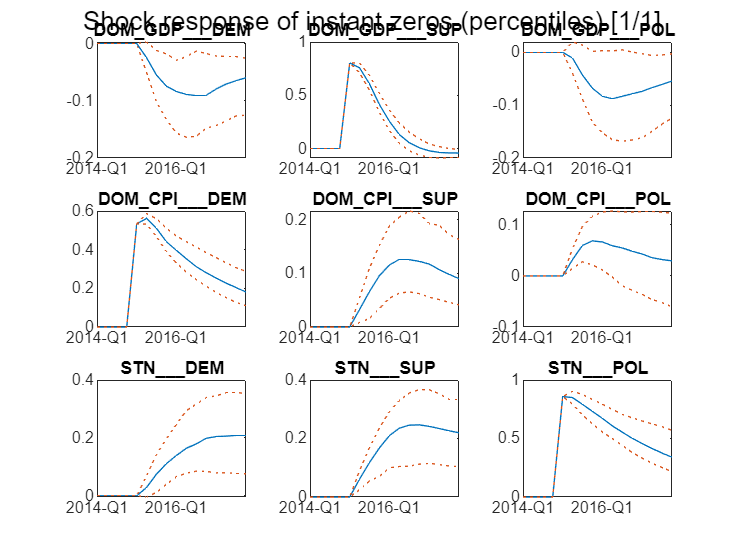


chartpack.responsePercentiles( ...
    respTbl1, modelS1 ...
    , "figureTitle", "Shock response of instant zeros (percentiles)" ...
);

### General restrictions


respTbl3 = modelS3.simulateResponses();


  (Minnesota) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



respTbl3 = tablex.apply(respTbl3, prctileFunc);
respTbl3 = tablex.flatten(respTbl3);

respTbl3

respTbl3 = 16×9 timetable
     Time                 DOM_GDP___DEM                          DOM_GDP___SUP                           DOM_GDP___POL                         DOM_CPI___DEM                         DOM_CPI___SUP                        DOM_CPI___POL                            STN___DEM                             STN___SUP                           STN___POL            
    _______    ___________________________________    ___________________________________    _____________________________________    ________________________________    ___________________________________    ________________________________    _____________________________________    ___________________

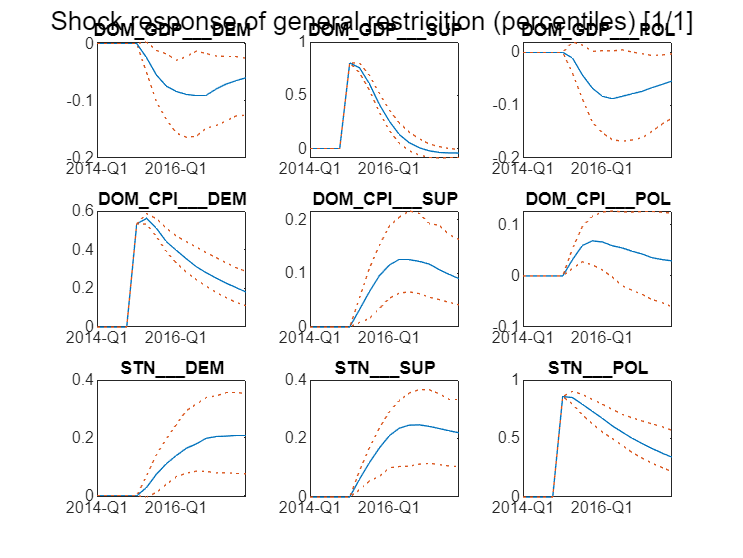


chartpack.responsePercentiles( ...
    respTbl1, modelS1 ...
    , "figureTitle", "Shock response of general restricition (percentiles)" ...
);

## **Historical shock decomposition**

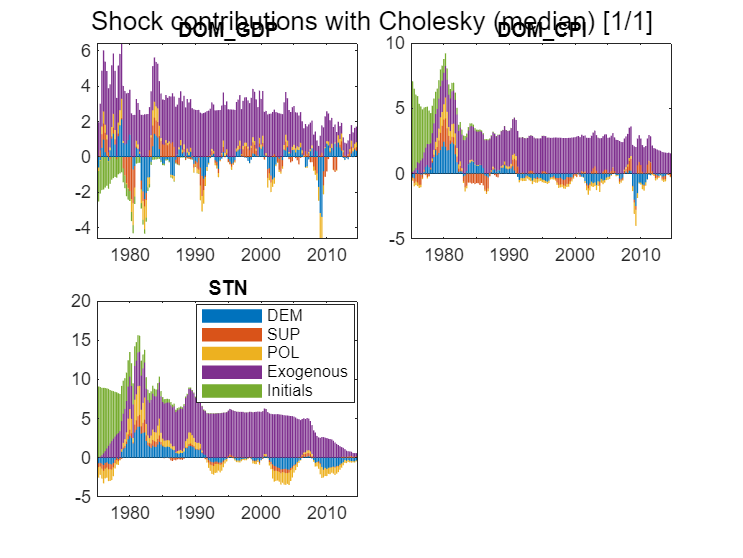

histContTbx = modelS3.calculateContributions();

histContMedTbx = tablex.apply(histContTbx, medianFunc);

chartpack.contributionsMedian( ...
    histContMedTbx, modelS3 ...
    , "figureTitle", "Shock contributions with Cholesky (median)" ...
);

## **Unconditional forecast shock decomposition**

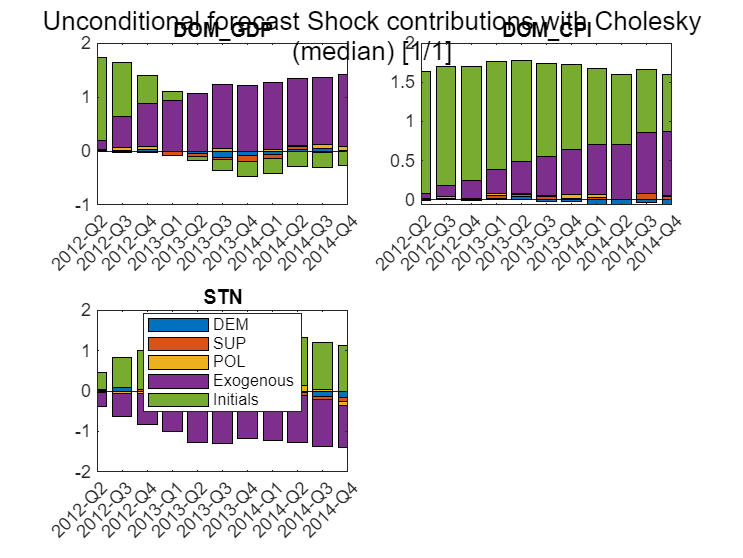


[uncFcastTbl1, uncFcastContribTbl1] = modelS3.forecast( ...
    fcastSpan, ...
    contributions=true ...
);


contMedTbx = tablex.apply(uncFcastContribTbl1, medianFunc);

chartpack.contributionsMedian( ...
    contMedTbx, modelS3 ...
    , "figureTitle", "Unconditional forecast Shock contributions with Cholesky (median)" ...
);

## **FEVD**

fevdTbx = modelS3.calculateFEVD();


  (Minnesota) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



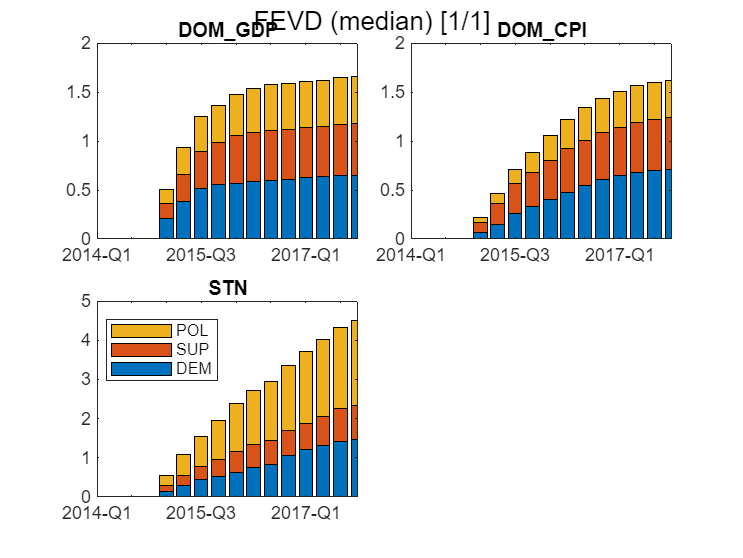


fevdMedTbx = tablex.apply(fevdTbx, medianFunc);

chartpack.contributionsMedian( ...
    fevdMedTbx, modelS3 ...
    , "figureTitle", "FEVD (median)" ...
);

## Conditional forecast

### Settig up the conditions and the forecast plan

condDataTbl = tablex.fromFile("condDataTbl.xlsx");
planTbl = tablex.readConditioningPlan("planTbl.xlsx");

### Settig up the forecast range 

cfcastStart = datex.shift(modelR1.Meta.EstimationEnd, 1); %The forecast starts after the estimation span.
cfcastEnd = datex.shift(modelR1.Meta.EstimationEnd, 12); 
cfcastSpan = datex.span(cfcastStart, cfcastEnd);

### Running conditional forecast with no simulation plan

[condFcastTbl1, condFcastContribTbl1] = modelS3.conditionalForecast( ...
    cfcastSpan, ...
    conditions=condDataTbl, ...
    plan=[], ...
    exogenousFrom = "conditions" ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




condFcastPrctilesTbl1 = tablex.apply(condFcastTbl1, prctileFunc);

### Running conditional forecast with simulation plan

[condFcastTbl2, condFcastContribTbl2] = modelS3.conditionalForecast( ...
    cfcastSpan, ...
    conditions=condDataTbl, ...
    plan=planTbl, ...
    exogenousFrom = "conditions" ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




condFcastPrctilesTbl2 = tablex.apply(condFcastTbl2, prctileFunc);

### Visualize the conditional forecast

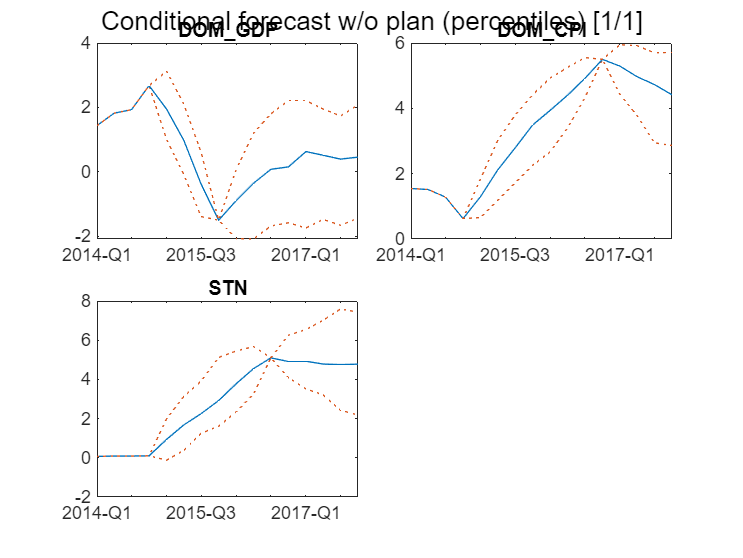

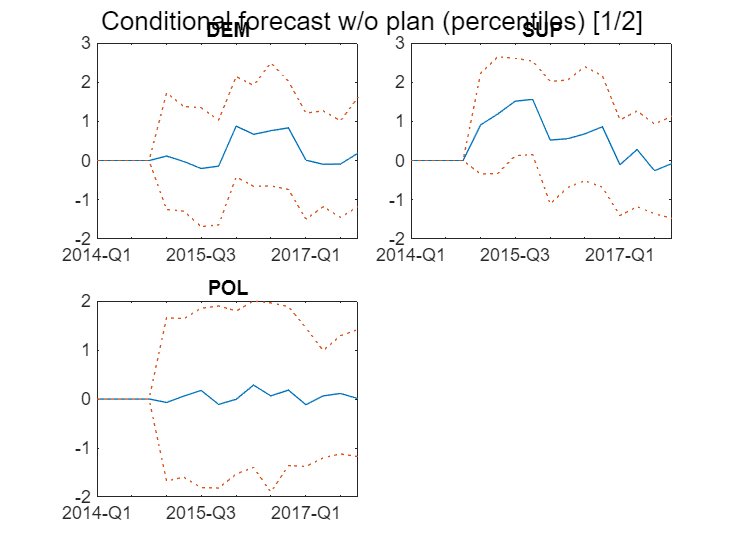

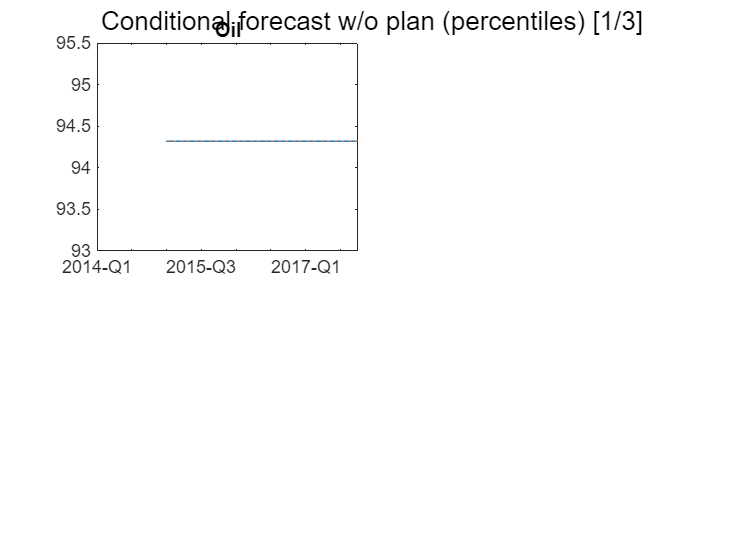

chartpack.conditionalForecastPercentiles( ...
    condFcastPrctilesTbl1, modelS3 ...
    , "figureTitle", "Conditional forecast w/o plan (percentiles)" ...
);

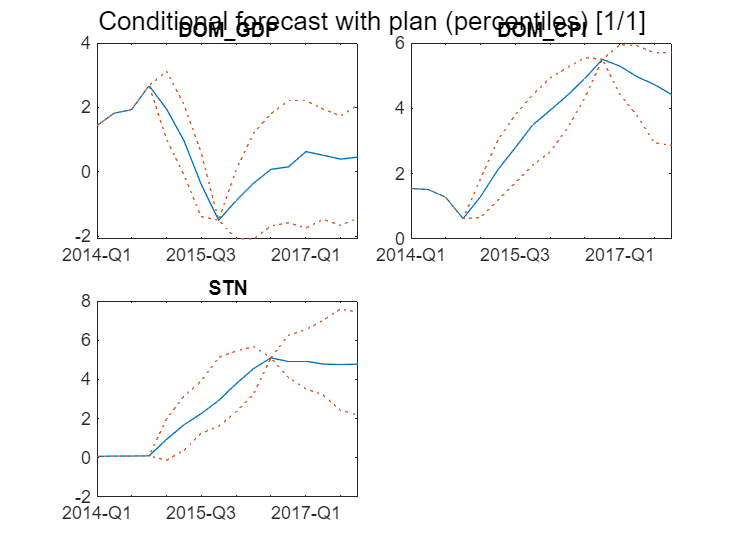

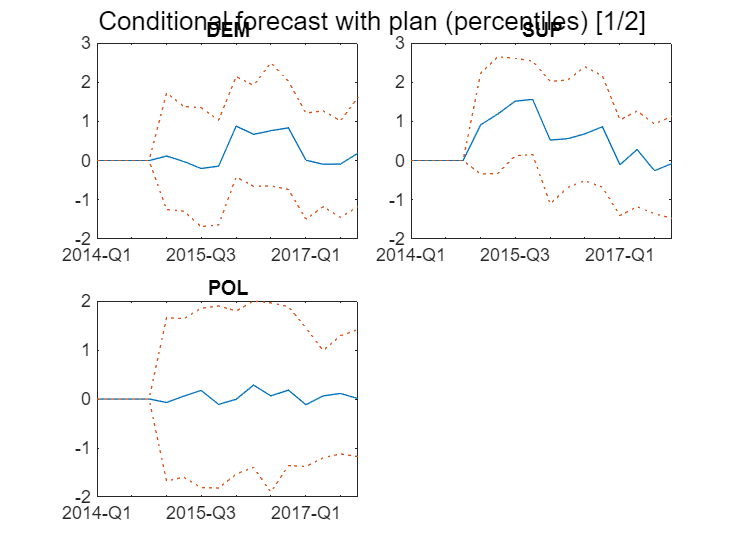

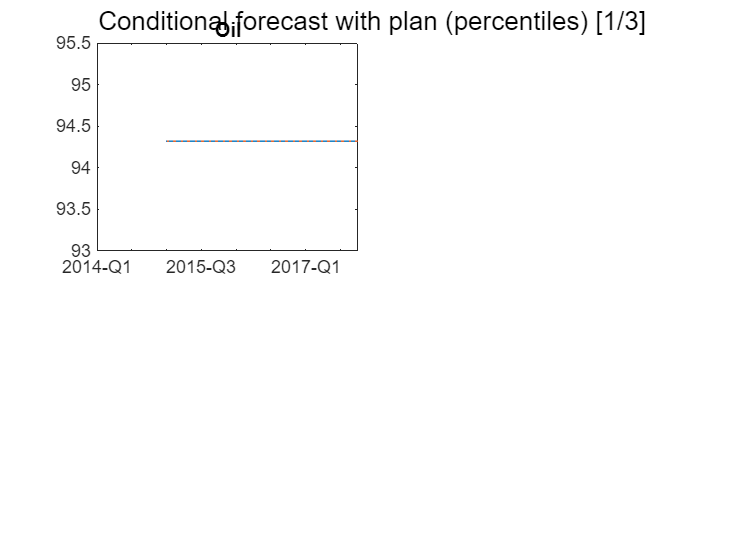


chartpack.conditionalForecastPercentiles( ...
    condFcastPrctilesTbl2, modelS3 ...
    , "figureTitle", "Conditional forecast with plan (percentiles)" ...
);